parpool("threads");% なしで54sec,

Starting parallel pool (parpool) using the 'threads' profile ...
Connected to parallel pool with 8 workers.


% delete(gcp('nocreate'));

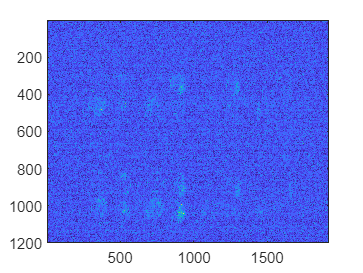

tic % タイマー取得
TIFImagePath = 'G:\My Drive\X-ray\Data\TIF\230920\shot015.tif';

% 生画像の取得
RawTIFImage = imread(TIFImagePath);

% 非線形フィルターをかける
imagesc(RawTIFImage);clim([49,60]);

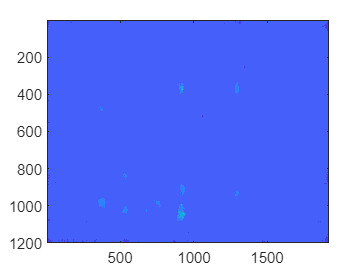

[Filtered1TIFImage,~] = imnlmfilt(RawTIFImage,'SearchWindowSize',51,'ComparisonWindowSize',13);
imagesc(Filtered1TIFImage);clim([49,60]);

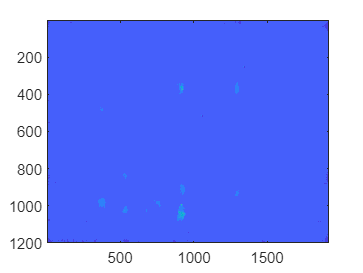

Filtered2TIFImage = imgaussfilt(Filtered1TIFImage);
imagesc(Filtered2TIFImage);clim([49,60]);

toc % タイマー回収

Elapsed time is 50.329766 seconds.


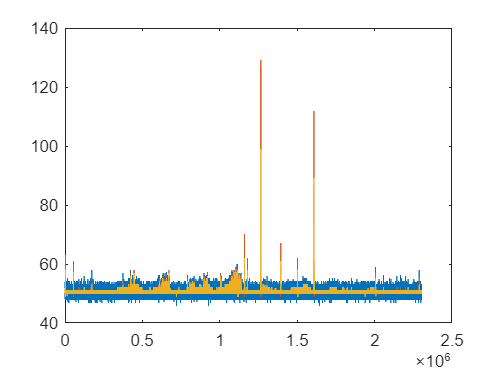

% 度数分布
num = numel(RawTIFImage);
RawEE = reshape(RawTIFImage,[1,num]);
plot((1:num),RawEE);hold on;
Filtered1EE = reshape(Filtered1TIFImage,[1,num]);
plot((1:num),Filtered1EE);
Filtered2EE = reshape(Filtered2TIFImage,[1,num]);
plot((1:num),Filtered2EE);hold off;